# PI Design with Root Locus

Design constraints.  Translate from second-order metrics to s-plane geometry.

close('all')
Tr = 0.9;
omega_n = 1.8/Tr

omega_n = 2

os = 2;
zeta = -log(os/100) / sqrt(pi^2 + log(os/100)^2)

zeta = 0.7797

- 
$$T_r \le 0.9 \: \text{s} \rightarrow \omega_n \ge 2.0 \: \text{rad/s$$


- 
$$\zeta \ge 0.78$$


Plot the root locus for three different designs.

G = zpk([],[-5, -5, -8],1);

I did this as a loop, but can do each manually if desired.

figure(1);
clf();
pizeros = [-1 -4 -7]

pizeros =     -1    -4    -7


lspecs = ["r", "b", "g"]

lspecs = 1×3 string array
    "r"    "b"    "g"


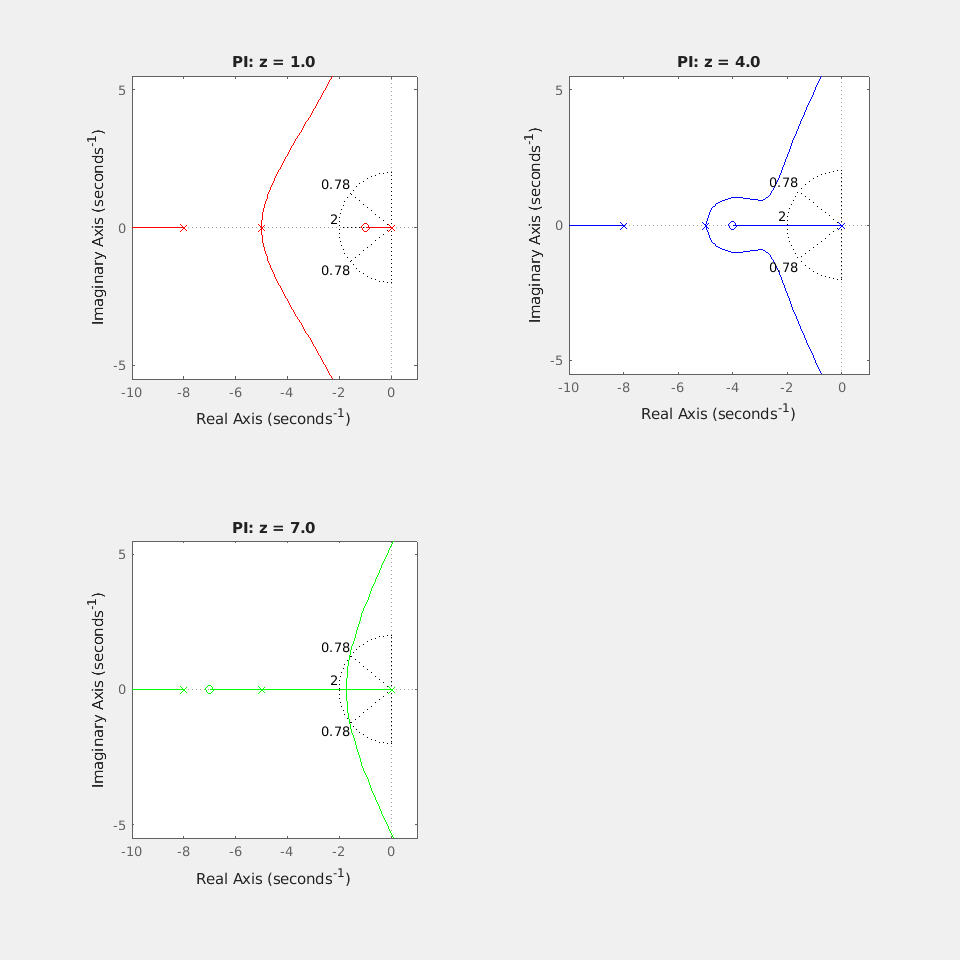

for ii = 1:length(pizeros)
    subplot(2,2,ii)
    pizero = pizeros(ii);
    D = zpk([pizero],[0],1);  
    L = D * G;
    rlocusplot(L, lspecs(ii))
    title(sprintf("PI: z = %.1f",-pizero))
    sgrid(zeta, omega_n);
    % Details to generate plots
    ax = gca;
    ax.AxesStyle.GridColor = [0 0 0];
    set(gcf,'Visible','on')
    axis([-10, 1, -5.5, 5.5])
    set(gcf,'position',[100, 100 , 960, 960])
end

The interactive plot and sgrid commands are a bit unreliable in the live-script.  You should see somethign like this...

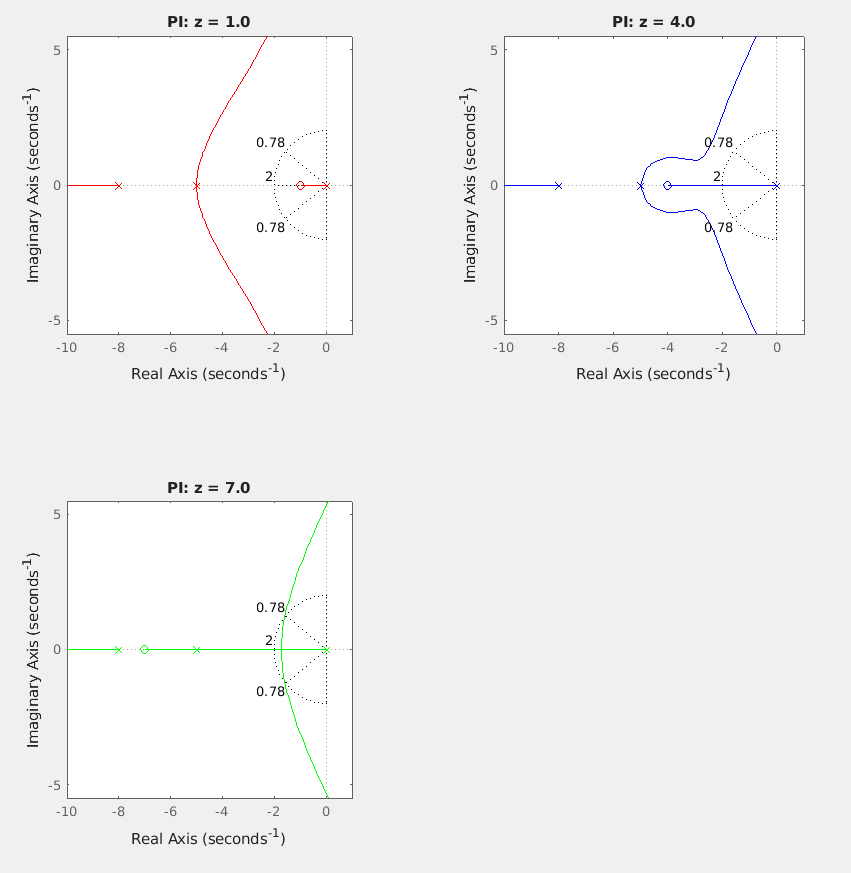

Let's consider each design option:

- z = 1.0:  While the second order pole pair would satisfy the design constraints, there is a real-axis segment near the imaginary axis, which tells us that no matter how high the gain, the closed-loop system will have a real pole that is far to the right, meaning it will have a time constant slower than our desired Tr.

- z = 7.0: Here there is not part of the root locus that is within our design constraints.

- z = 4.0:  There is a section of both the real-axis segment and the second order poles trajectory that looks like it will satisfy the constraints.  The question is can we find a gain value places all three closed-loop poles within the constraints - but this is the only option that appears to have a solution.

Replot just the for $z = 4$design, appears to be the only design that satisfies our constrains for $\zeta$and $\omega_n$.

Plot the root locus for this design.

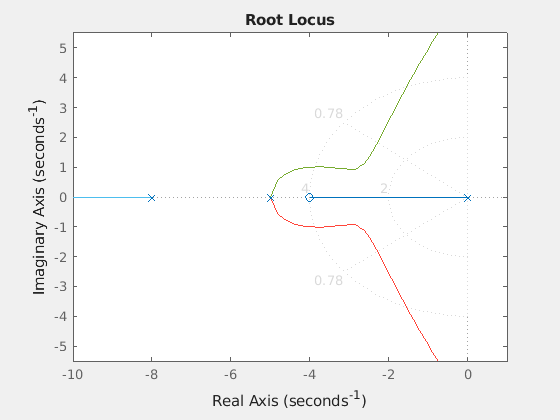

pizero = -4;
D = zpk([pizero],[0],1);  
L = D * G;
figure(2);
clf();
rlocus(L)
sgrid(zeta, [omega_n, 4]);
axis([-10, 1, -5.5, 5.5])


set(gcf,'Visible','on')

Use the interactive tool to choose a gain value that should satisfy the constraints.

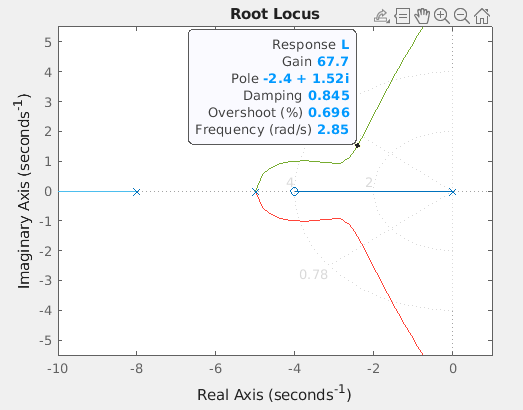

K = 67.4;

Overlay the predicted closed-loop pole locations

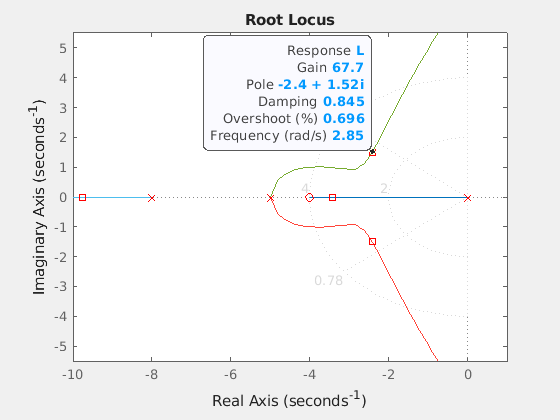

hold on
rlocus(L, K, "rs")

Close the loop and report the results.

T = feedback(K*L, 1);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.41e+00 + 1.50e+00i     8.48e-01       2.84e+00         4.15e-01    
 -2.41e+00 - 1.50e+00i     8.48e-01       2.84e+00         4.15e-01    
 -3.42e+00                 1.00e+00       3.42e+00         2.92e-01    
 -9.76e+00                 1.00e+00       9.76e+00         1.02e-01    


s=stepinfo(T)

s = struct with fields:
         RiseTime: 1.0281
    TransientTime: 1.6995
     SettlingTime: 1.6995
      SettlingMin: 0.9034
      SettlingMax: 1.0043
        Overshoot: 0.4268
       Undershoot: 0
             Peak: 1.0043
         PeakTime: 2.3870


[pp, zz] = pzmap(T)

pp =   -9.7573 + 0.0000i
  -2.4116 + 1.5048i
  -2.4116 - 1.5048i
  -3.4195 + 0.0000i


zz = -4.0000

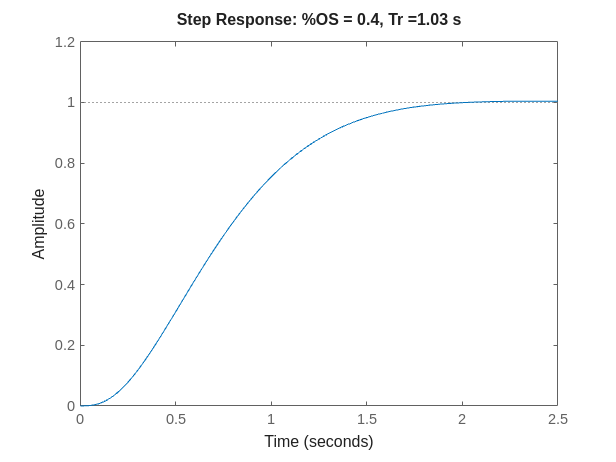

figure(3);
clf()
step(T)
title(sprintf("Step Response: %%OS = %.1f, Tr =%.2f s", s.Overshoot, s.RiseTime ))


$$D(s) = 67.4\left( \frac{s+4}{s} \right)$$


The final rise-time is a bit higher than our goal of 0.9 s.  This is because our mapping of the design constrains into the s-plane is based just on a canonical, second-order system response.  The actual closed loop transfer function is more complex with 5 poles and a zero, so even though all the poles are within our s-plane design constraints, the response is a bit slower than desired.

T


T =
 
                 67.4 (s+4)
  -----------------------------------------
  (s+9.757) (s+3.419) (s^2 + 4.823s + 8.08)
 
Continuous-time zero/pole/gain model.
Model Properties
